Plot original Runge's function

xx = 0 : 0.05 : 1

xx =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000


yy = 1 ./ (1+25.*xx.^2)

yy =     1.0000    0.9412    0.8000    0.6400    0.5000    0.3902    0.3077    0.2462    0.2000    0.1649    0.1379    0.1168    0.1000    0.0865    0.0755    0.0664    0.0588    0.0525    0.0471    0.0424    0.0385


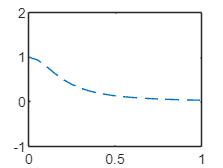

plot(xx,yy,'--')

axis([0 1 -1 2])


xtest = 0.6

xtest = 0.6000

yt = 1 ./ (1+25.*xtest.^2)

yt = 0.1000

Fit with 2th-order polynomial

x = linspace(0, 1 ,3)

x =          0    0.5000    1.0000


y = 1 ./ (1+25.*x.^2)

y =     1.0000    0.1379    0.0385


p2 = polyfit(x,y,2)

p2 =     1.5252   -2.4867    1.0000


yy2 = polyval(p2,xx)

yy2 =     1.0000    0.8795    0.7666    0.6613    0.5637    0.4736    0.3912    0.3165    0.2493    0.1898    0.1379    0.0937    0.0570    0.0280    0.0066   -0.0071   -0.0133   -0.0118   -0.0027    0.0141    0.0385


plot(xx,yy,'k--')
hold on
plot(x,y,'*g')
plot(xx,yy2,'r--')
hold off
xtest = 0.6

xtest = 0.6000

yp2 = polyval(p2,xtest)

yp2 = 0.0570

er = (yt-yp2)/yt

er = 0.4297

er = er *100

er = 42.9708

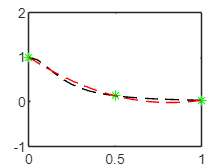

axis([0 1 -1 2])

Fit with 3th-order polynomial


x = linspace(0, 1 ,4)

x =          0    0.3333    0.6667    1.0000


y = 1 ./ (1+25.*x.^2)

y =     1.0000    0.2647    0.0826    0.0385


p2 = polyfit(x,y,3)

p2 =    -1.8681    4.3573   -3.4507    1.0000


yy2 = polyval(p2,xx)

yy2 =     1.0000    0.8381    0.6966    0.5741    0.4692    0.3805    0.3065    0.2459    0.1973    0.1593    0.1304    0.1094    0.0947    0.0849    0.0788    0.0748    0.0716    0.0678    0.0619    0.0526    0.0385


plot(xx,yy,'k--')
hold on
plot(x,y,'*g')
plot(xx,yy2,'r--')
hold off
xtest = 0.6

xtest = 0.6000

yp3 = polyval(p2,xtest)

yp3 = 0.0947

er = (yt-yp3)/yt

er = 0.0533

er = er *100

er = 5.3302

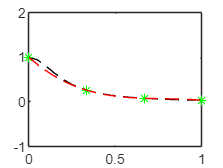


axis([0 1 -1 2])

Fit with 4th-order polynomial


x = linspace(0, 1 ,5)

x =          0    0.2500    0.5000    0.7500    1.0000


y = 1 ./ (1+25.*x.^2)

y =     1.0000    0.3902    0.1379    0.0664    0.0385


p2 = polyfit(x,y,4)

p2 =     0.4215   -2.5167    4.5627   -3.4290    1.0000


yy2 = polyval(p2,xx)

yy2 =     1.0000    0.8396    0.7003    0.5800    0.4773    0.3902    0.3174    0.2572    0.2082    0.1688    0.1379    0.1141    0.0962    0.0830    0.0734    0.0664    0.0610    0.0563    0.0515    0.0458    0.0385


plot(xx,yy,'k--')
hold on
plot(x,y,'*g')
plot(xx,yy2,'r--')
hold off
xtest = 0.6

xtest = 0.6000

yp4 = polyval(p2,xtest)

yp4 = 0.0962

er = (yt-yp4)/yt

er = 0.0381

er = er*100

er = 3.8120

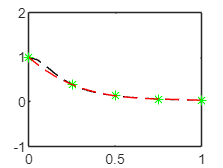

axis([0 1 -1 2])

Assume that we have 5 data points from this Runge's function at x = 0.00,  0.25,  0.50,  0.75,  1.00

When y = 0.5, find the correct value of x analytically

x = 0:0.25:1 

x =          0    0.2500    0.5000    0.7500    1.0000


0.5 = 1 ./ (1+25.*xx.^2)

Now assume that we don't know the Runge's function.  Using quadratic interpolation and the quadratic formula to determine the value of x numerically. (use the first three points to fit quadratic polynomial)